clc; clear; close all;


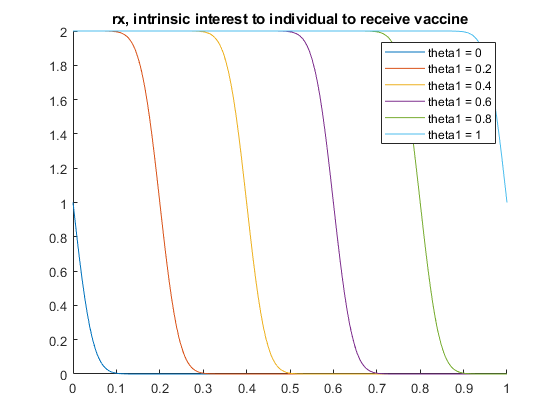

syms x;

%rx = intrinsic interest to individual to receive vaccine
figure(1);
hold on;
for theta1 = 0:0.2:1
    rx = 1 - erf(20*(x - theta1));
    legendtxt = ['theta1 = ', num2str(theta1)];
    fplot(rx, [0,1], 'DisplayName', legendtxt);
end
title('rx, intrinsic interest to individual to receive vaccine');
legend show;

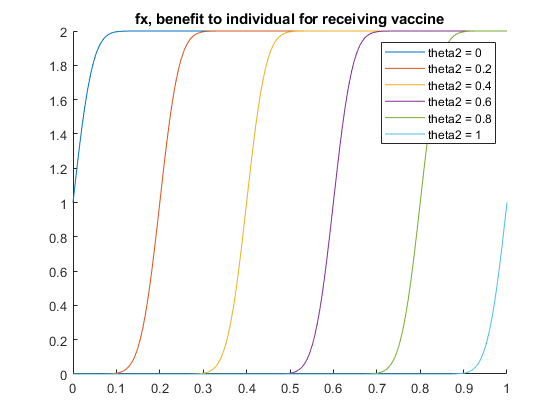


%fx = benefit to individual for receiving vaccine
figure(2);
hold on;
for theta2 = 0:0.2:1
    fx = 1 + erf(20*(x - theta2));
    legendtxt = ['theta2 = ', num2str(theta2)];
    fplot(fx, [0,1], 'DisplayName', legendtxt);
end
title('fx, benefit to individual for receiving vaccine')
legend show;

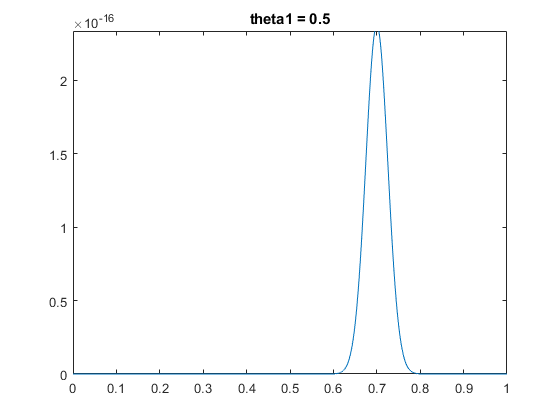

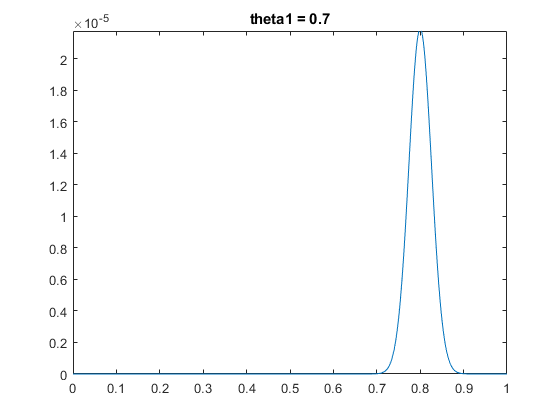

theta1 = [0.5; 0.7; 0.92];
theta2 = 0.9;
fx = 1 + erf(20*(x - theta2));
for i = 1:length(theta1)
    figure(i+2);
    rx = 1 - erf(20*(x - theta1(i)));
    fplot(fx*rx, [0,1]);
    title(['theta1 = ' , num2str(theta1(i))]);
end

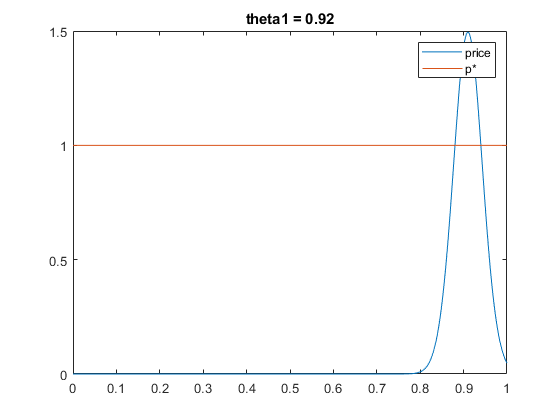


hold on;
%Add arbitrary price at 1
plot([0,1], [1,1]);
legend('price', 'p*');